# Implementation of DMD Algorithm

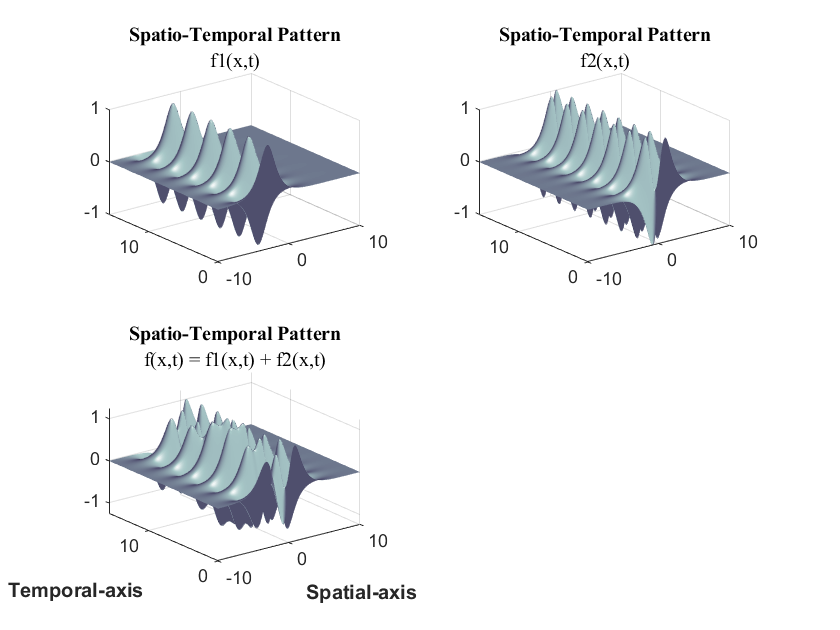

clc;
close all;
clear all;

% Generating grid
x = linspace(-10,10,400);
t = linspace(0,5*pi,200);
dt = t(2) - t(1);
[x_grid, t_grid] = meshgrid(x,t);

% Creation of spatio-temporal patterns(Patterns that vary with space and time)
f1 = sech(x_grid+3).*(1*exp(1i*2.3*t_grid));
f2 = (sech(x_grid).*tanh(x_grid)).*(2*exp(1i*2.8*t_grid));
f = f1 + f2;
[u, s, v] = svd(f.');

% Plotting the spatio-temporal patterns f1, f2, f
figure(1)
subplot(2,2,1)
surfl(x_grid,t_grid,real(f1));
shading interp;
colormap bone;
title("Spatio-Temporal Pattern","f1(x,t)",'FontName','times new roman','FontSize',12)

subplot(2,2,2)
surfl(x_grid,t_grid,real(f2));
shading interp;
colormap bone;
title("Spatio-Temporal Pattern","f2(x,t)",'FontName','times new roman','FontSize',12)

subplot(2,2,3)
surfl(x_grid,t_grid,real(f));
shading interp;
colormap bone;
xlabel('Spatial-axis','FontSize',10,'FontWeight','bold'); 
ylabel('Temporal-axis','FontSize',10,'FontWeight','bold');
title("Spatio-Temporal Pattern","f(x,t) = f1(x,t) + f2(x,t)",'FontName','times new roman','FontSize',12)

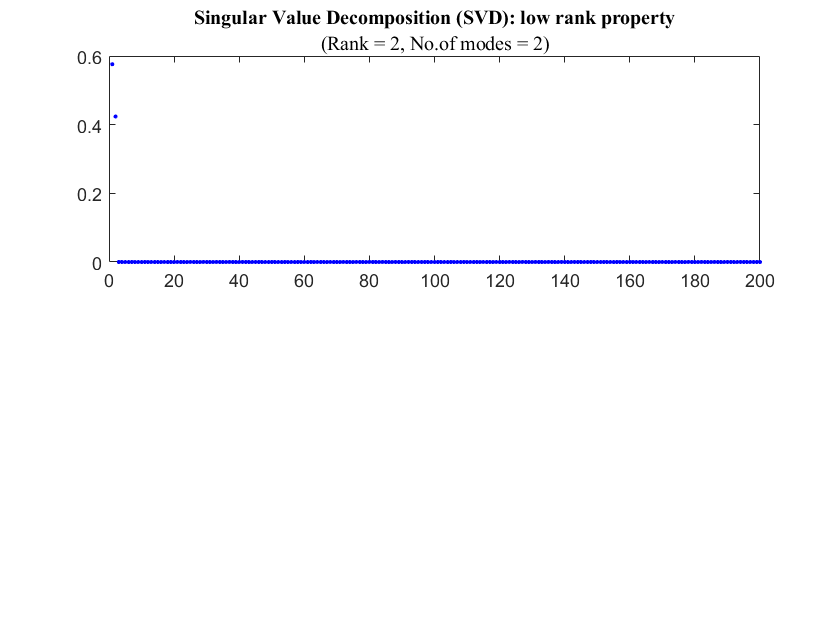

figure(2)
subplot(2,1,1);
plot(diag(s) / sum(diag(s)),'b.');
title('Singular Value Decomposition (SVD): low rank property','(Rank = 2, No.of modes = 2)','FontName','times new roman','FontSize',12)

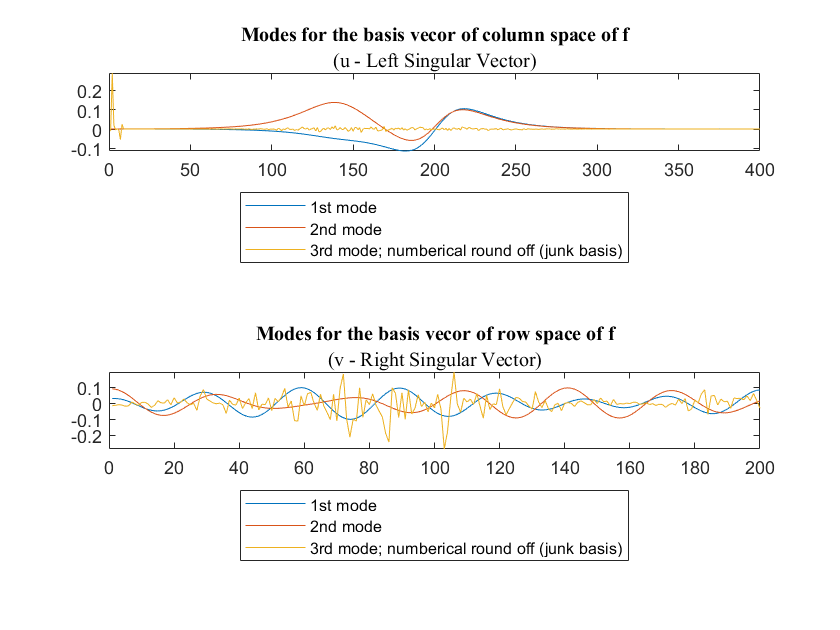

figure(3)
subplot(2,1,1)
plot(real(u(:,1:3)));
title('Modes for the basis vecor of column space of f','(u - Left Singular Vector)','FontName','times new roman','FontSize',12);
legend('1st mode', '2nd mode', '3rd mode; numberical round off (junk basis)','Location','southoutside');

subplot(2,1,2)
plot(real(v(:,1:3)));
title('Modes for the basis vecor of row space of f','(v - Right Singular Vector)','FontName','times new roman','FontSize',12);
legend('1st mode', '2nd mode', '3rd mode; numberical round off (junk basis)','Location','southoutside');

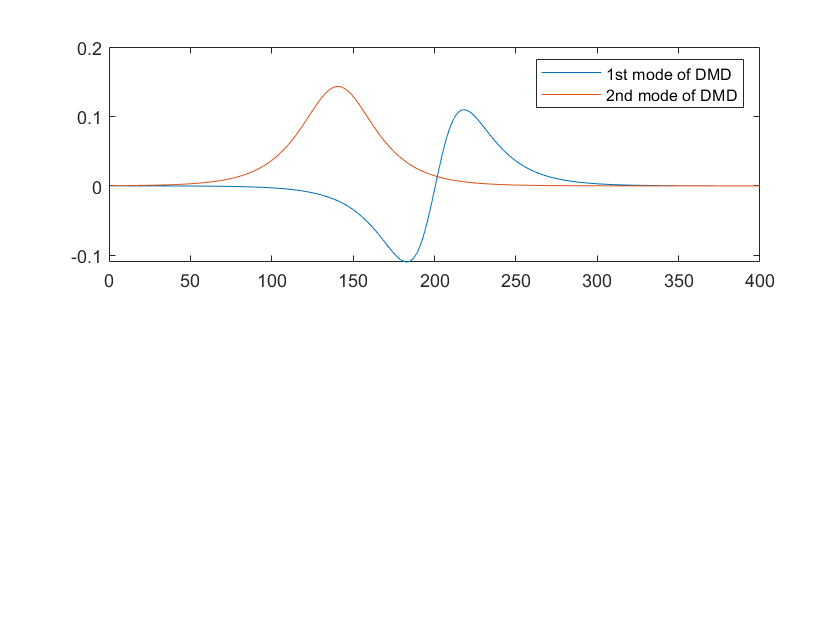

% Dynamic Mode Decomposition (DMD) - Algorithm
X = f.';
X1 = X(:,1:end-1);
X2 = X(:,2:end);

% Performing singular value decomposition - SVD
r = 2; % Rank-r truncation
[U, S, V] = svd(X1, "econ");
Ur = U(:,1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Creating low-rank subspace matrix
%(similarity transform, least-square fit matrix, low-rank subspace matrix)
A_tilde = Ur'*X2*Vr*Sr^(-1);

% Eigen_Decomposition
[eig_vec, eig_val] = eig(A_tilde);

% Real space DMD mode
phi = X2*Vr*Sr^(-1)*eig_vec;   % DMD modes
lamdba = diag(eig_val);       % eigen value
omega = log(lamdba)/dt; % log of eigen value

figure(4)
subplot(2,1,1);
plot(real(u(:, 1:2)))
legend('1st mode of SVD','2nd mode of SVD');
plot(real(phi))
legend('1st mode of DMD','2nd mode of DMD');

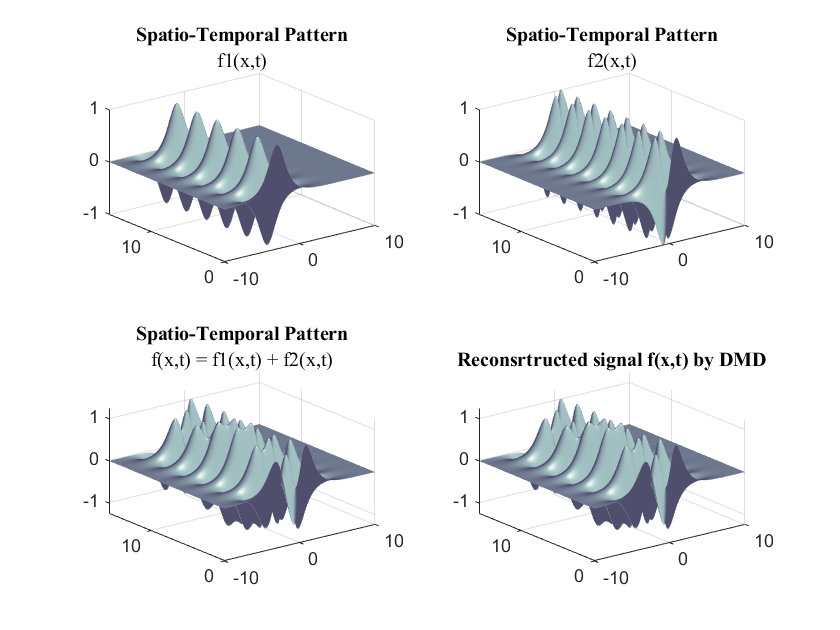

% Reconstructing the signal
X1 = X(:,1); % time = 0
b = pinv(phi)*X1; % initial value; 
t_dynamic = zeros(r,length(t));
for i = 1:length(t)
    t_dynamic(:,i) = (b.*exp(omega*t(i)));
end
f_dmd = phi*t_dynamic;

% Plot of the reconstructed signal with dmd
figure(5)
subplot(2,2,1)
surfl(x_grid,t_grid,real(f1));
shading interp;
colormap bone;
title("Spatio-Temporal Pattern","f1(x,t)",'FontName','times new roman','FontSize',12)

subplot(2,2,2)
surfl(x_grid,t_grid,real(f2));
shading interp;
colormap bone;
title("Spatio-Temporal Pattern","f2(x,t)",'FontName','times new roman','FontSize',12)

subplot(2,2,3)
surfl(x_grid,t_grid,real(f));
shading interp;
colormap bone;
title("Spatio-Temporal Pattern","f(x,t) = f1(x,t) + f2(x,t)",'FontName','times new roman','FontSize',12)

subplot(2,2,4)
surfl(x_grid,t_grid,real((f_dmd).'));
shading interp;
colormap bone;
title("Reconsrtructed signal f(x,t) by DMD",'FontName','times new roman','FontSize',12)

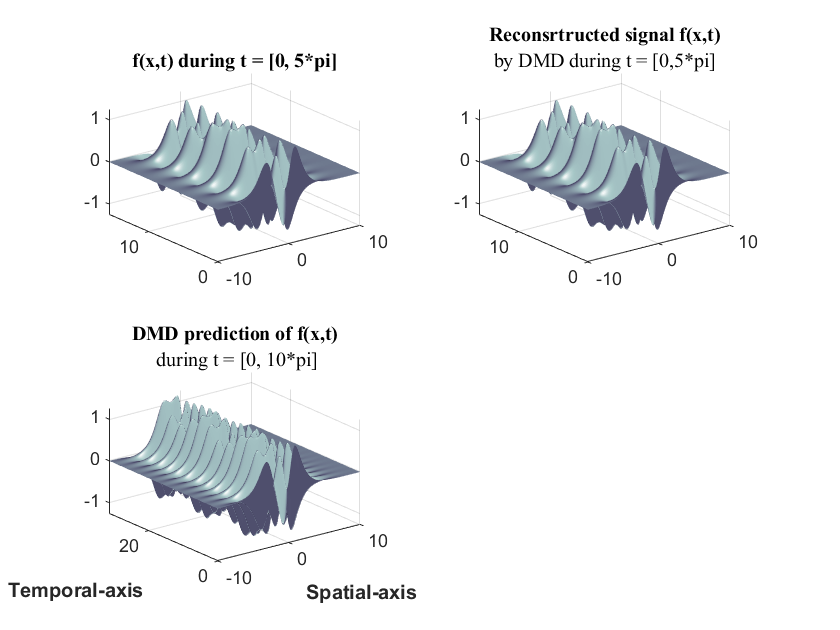

% Predicting the future state using time dynamics
t_ext = linspace(0,10*pi, 400);
[x_grid_ext, t_grid_ext] = meshgrid(x, t_ext);
t_ext_dynamic = zeros(r, length(t_ext));
for i = 1:length(t_ext)
    t_ext_dynamic(:,i) = (b.*exp(omega*t_ext(i)));
end
f_dmd_ext = phi*t_ext_dynamic;

% Plotting the signals
figure(6)
subplot(2,2,1)
surfl(x_grid,t_grid,real(f));
shading interp;
colormap bone;
title("f(x,t) during t = [0, 5*pi]",'FontName','times new roman','FontSize',12)

subplot(2,2,2)
surfl(x_grid,t_grid,real(f_dmd).');
shading interp;
colormap bone;
title('Reconsrtructed signal f(x,t)','by DMD during t = [0,5*pi]','FontName','times new roman','FontSize',12)

subplot(2,2,3)
surfl(x_grid_ext,t_grid_ext,real(f_dmd_ext).');
shading interp;
colormap bone;
xlabel('Spatial-axis','FontSize',10,'FontWeight','bold'); 
ylabel('Temporal-axis','FontSize',10,'FontWeight','bold');
title('DMD prediction of f(x,t)',' during t = [0, 10*pi]','FontName','times new roman','FontSize',12)